Set up input parameters

I = 'circles.png';
sigma = 6;
threshold = 29;
radius_range = [5,15];

IG = im2gray(imread(I));
IB = imgaussfilt(IG, sigma);
IE = edge(IB, 'roberts');

Hough transform

[centers, radii] = imfindcircles(IE, radius_range);

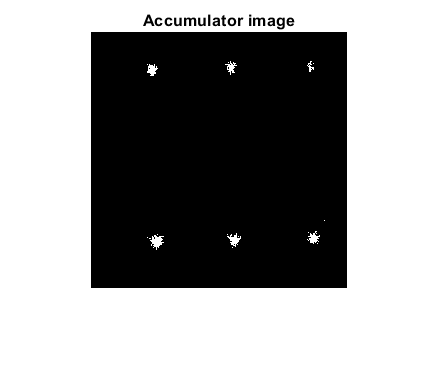

r_m = mean(radii, 1);

acc_img = zeros(size(IE));
for ax = 1:size(IE, 1)
    for ay = 1:size(IE, 2)
        th = 0:pi/50:2*pi;
        x_pos = r_m * cos(th) + ax;
        y_pos = r_m * sin(th) + ay;
        coord_matrix = [x_pos; y_pos];
        

        correct_coord = [];
        for i = 1:size(coord_matrix, 2)
            if(coord_matrix(1, i) >= 1 && coord_matrix(2, i) >= 1)
                if(coord_matrix(1, i) <= size(IE, 2) && ...
                        coord_matrix(2, i) <= size(IE, 1))
                    correct_coord = [correct_coord floor(coord_matrix(:, i))];
                end
            end
        end

        supp = 0;
        for j = 1:size(correct_coord, 2)
            cx = correct_coord(1, j);
            cy = correct_coord(2, j);
            value = IE(cx, cy);
            maximum(cx, cy) = 255;
            if(value == 1)
                supp = supp + 1;
            end
        end
        acc_img(ax, ay) = supp;
    end
end
acc_img2 = acc_img;
for i = 1:size(acc_img, 1)
    for j = 1:size(acc_img, 2)
        if(acc_img(i,j) <= 17)
            acc_img(i,j) = 0;
        end
    end
end
figure;
imshow(acc_img);
title('Accumulator image');

Postprocessing of Hought transform and detection of objects

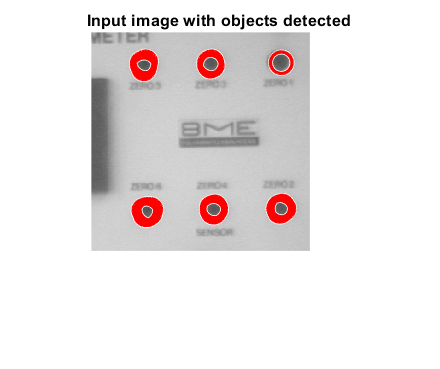

for i = 1:size(acc_img2, 1)
    for j = 1:size(acc_img2, 2)
        if(acc_img2(i,j) <= threshold)
            acc_img2(i,j) = 0;
        end
    end
end
centers = [];
radii = [];
for i = 1:size(acc_img2, 1)
    for j = 1:size(acc_img2, 2)
        if(acc_img2(i, j) > 0)
            centers = [centers; [j i]];
            radii = [radii; r_m];
        end
    end
end
figure;
hold on;
imshow(I);
viscircles(centers, radii, 'Color', 'r');
title('Input image with objects detected');
hold off;

I = 'blood.png';
sigma = 5;
threshold = 30;
radius_range = [5,10];


IG = im2gray(imread(I));
IE = edge(IG, 'roberts');

[centers, radii] = imfindcircles(IE, radius_range);

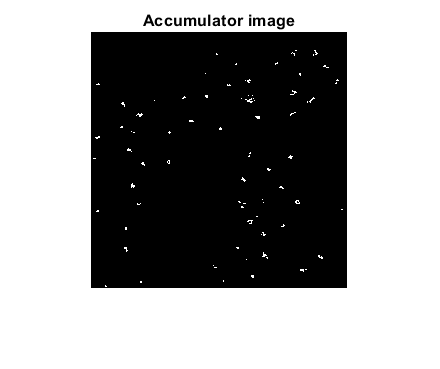

r_m = mean(radii, 1);

acc_img = zeros(size(IE));
for ax = 1:size(IE, 1)
    for ay = 1:size(IE, 2)
        th = 0:pi/50:2*pi;
        x_pos = r_m * cos(th) + ax;
        y_pos = r_m * sin(th) + ay;
        coord_matrix = [x_pos; y_pos];
        

        correct_coord = [];
        for i = 1:size(coord_matrix, 2)
            if(coord_matrix(1, i) >= 1 && coord_matrix(2, i) >= 1)
                if(coord_matrix(1, i) <= size(IE, 2) && ...
                        coord_matrix(2, i) <= size(IE, 1))
                    correct_coord = [correct_coord floor(coord_matrix(:, i))];
                end
            end
        end

        supp = 0;
        for j = 1:size(correct_coord, 2)
            cx = correct_coord(1, j);
            cy = correct_coord(2, j);
            value = IE(cx, cy);
            maximum(cx, cy) = 255;
            if(value == 1)
                supp = supp + 1;
            end
        end
        acc_img(ax, ay) = supp;
    end
end
acc_img2 = acc_img;
for i = 1:size(acc_img, 1)
    for j = 1:size(acc_img, 2)
        if(acc_img(i,j) <= 25)
            acc_img(i,j) = 0;
        end
    end
end
figure;
imshow(acc_img);
title('Accumulator image');

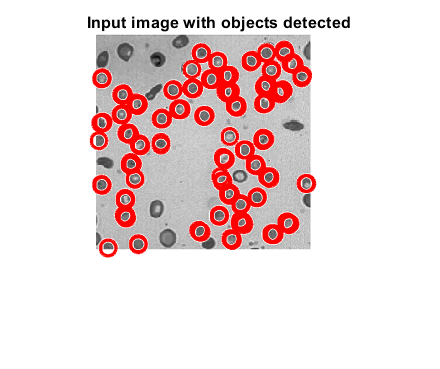

for i = 1:size(acc_img2, 1)
    for j = 1:size(acc_img2, 2)
        if(acc_img2(i,j) <= threshold)
            acc_img2(i,j) = 0;
        end
    end
end
centers = [];
radii = [];
for i = 1:size(acc_img2, 1)
    for j = 1:size(acc_img2, 2)
        if(acc_img2(i, j) > 0)
            centers = [centers; [j i]];
            radii = [radii; r_m];
        end
    end
end
figure;
hold on;
imshow(I);
viscircles(centers, radii, 'Color', 'r');
title('Input image with objects detected');
hold off;

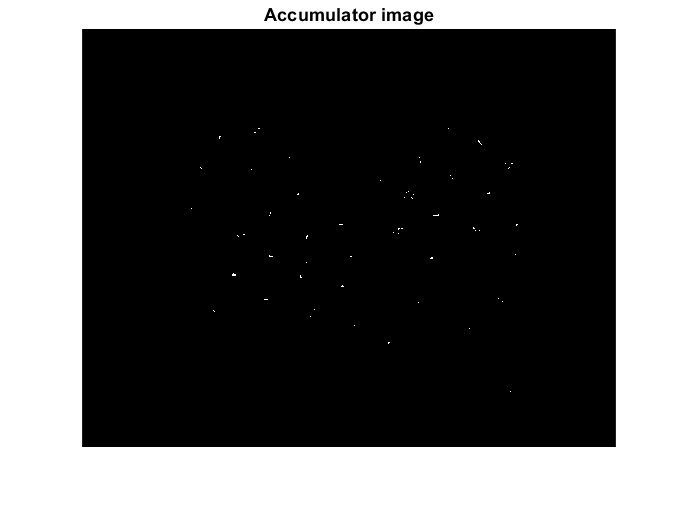

I = 'cable.png';
sigma = 2.2;
threshold = 27;
radius_range = [10,80];

IG = im2gray(imread(I));
IB = imgaussfilt(IG, sigma);
IE = edge(IB, 'canny');

[centers, radii] = imfindcircles(IE, radius_range);

r_m = mean(radii, 1);

acc_img = zeros(size(IE));
for ax = 1:size(IE, 1)
    for ay = 1:size(IE, 2)
        th = 0:pi/50:2*pi;
        x_pos = r_m * cos(th) + ax;
        y_pos = r_m * sin(th) + ay;
        coord_matrix = [x_pos; y_pos];
        

        correct_coord = [];
        for i = 1:size(coord_matrix, 2)
            if(coord_matrix(1, i) >= 1 && coord_matrix(2, i) >= 1)
                if(coord_matrix(1, i) <= size(IE, 1) && ...
                        coord_matrix(2, i) <= size(IE, 2))
                    correct_coord = [correct_coord floor(coord_matrix(:, i))];
                end
            end
        end

        supp = 0;
        for j = 1:size(correct_coord, 2)
            cx = correct_coord(1, j);
            cy = correct_coord(2, j);
            value = IE(cx, cy);
            maximum(cx, cy) = 255;
            if(value == 1)
                supp = supp + 1;
            end
        end
        acc_img(ax, ay) = supp;
    end
end
acc_img2 = acc_img;
for i = 1:size(acc_img, 1)
    for j = 1:size(acc_img, 2)
        if(acc_img(i,j) <= threshold)
            acc_img(i,j) = 0;
        end
    end
end
figure;
imshow(acc_img);
title('Accumulator image');

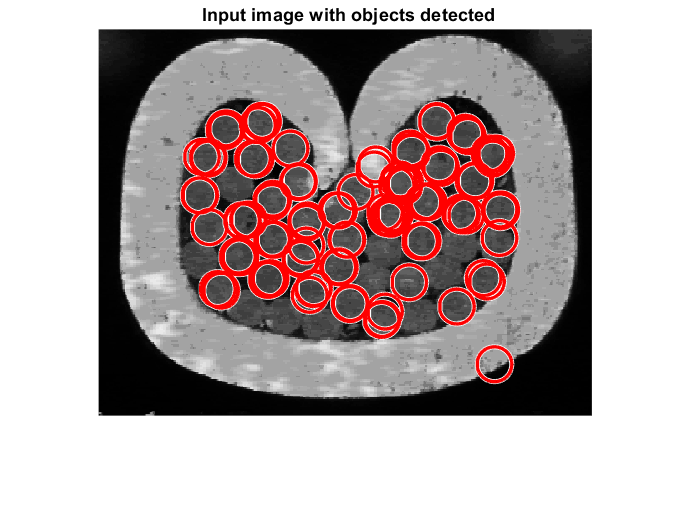


for i = 1:size(acc_img2, 1)
    for j = 1:size(acc_img2, 2)
        if(acc_img2(i,j) <= threshold)
            acc_img2(i,j) = 0;
        end
    end
end
centers = [];
radii = [];
for i = 1:size(acc_img2, 1)
    for j = 1:size(acc_img2, 2)
        if(acc_img2(i, j) > 0)
            centers = [centers; [j i]];
            radii = [radii; r_m];
        end
    end
end
figure;
hold on;
imshow(I);
viscircles(centers, radii, 'Color', 'r');
title('Input image with objects detected');
hold off;


export("t3t.mlx");